# Geometrically nonlinear von Karman beam

Finite element model from the following reference:

 Jain, S., Tiso, P., & Haller, G. (2018). Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds. *Journal of Sound and Vibration*, *423*, 195–211. [https://doi.org/10.1016/J.JSV.2018.01.049](https://doi.org/10.1016/J.JSV.2018.01.049)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

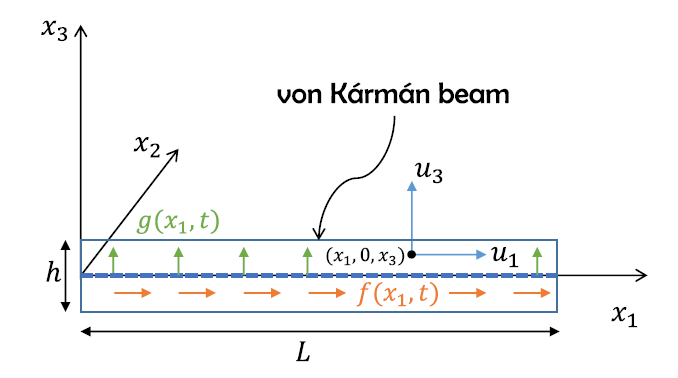

**system parameters**

nElements = 10;
epsilon = 5e-4;

## generate model

Building FE model


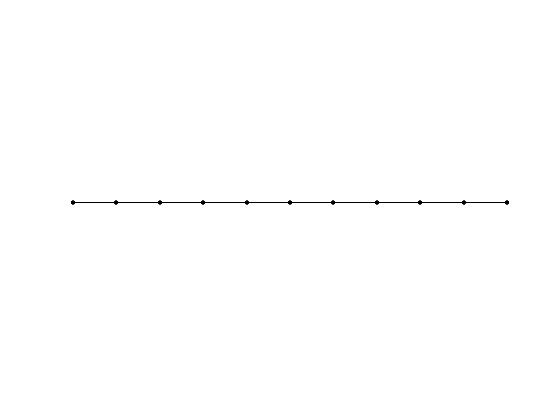

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


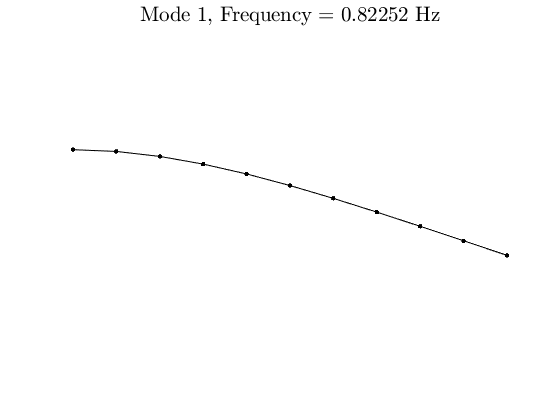

Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:00


[M,C,K,fnl,f_0,outdof] = build_model(nElements);

n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 30


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 60


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.691472e-04
modal damping ratio for 2 mode is 2.313481e-03
modal damping ratio for 3 mode is 6.479248e-03
modal damping ratio for 4 mode is 1.270560e-02
modal damping ratio for 5 mode is 2.103617e-02

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0000 + 0.0517i
  -0.0000 - 0.0517i
  -0.0007 + 0.3239i
  -0.0007 - 0.3239i
  -0.0059 + 0.9071i
  -0.0059 - 0.9071i
  -0.0226 + 1.7786i
  -0.0226 - 1.7786i
  -0.0620 + 2.9444i
  -0.0620 - 2.9444i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3247
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i

sigma_in = 3247


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = [3,5,7]; % Approximation order

setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
% set(S.FRCOptions, 'method','level set')
set(S.FRCOptions, 'method','continuation ep', 'z0', 1e-4*[1; 1]) % 'level set' 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range around the first natural frequency

omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.9 1.1];

extract forced response curve

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i

sigma_out = 3247
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 

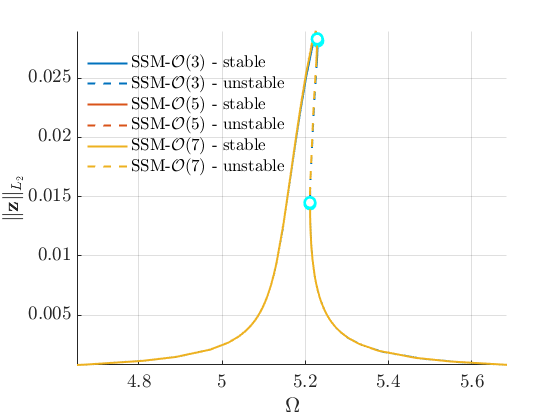

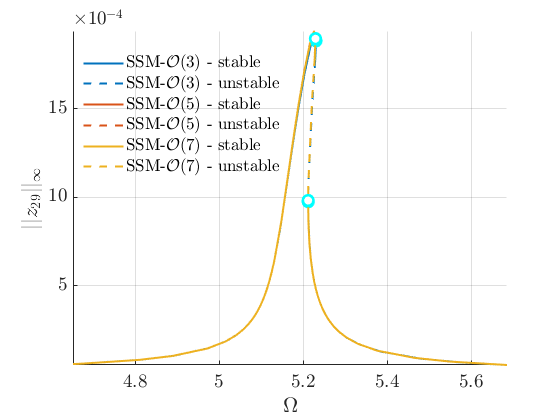

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 +32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i
  -0.0749 -32.3886i

sigma_out = 3247
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 

FRC = S.extract_FRC('freq',omegaRange,order);

figFRC = gcf;